% %liste de matched cells
% %liste assembly day1
% %liste assembly day 2
% clear
% % 
% load('/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/stability/listani444152-29.mat')
% % %%444152 28-29
% pathmatch=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/stability/' ...
%     '444152_plane0/track2p28-29/plane0_match_mat.mat'];
% % % 28
% % path_day1=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis' ...
% %     '/stability/444152_plane0/track2p28-29/24_09_24_12_04_33P2M_444152_' ...
% %     '221128_plane1_2023_01_12.09-12-58/results.mat'];
% % % 
% % % path_day1=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/' ...
% % %     'stability/444152_plane0/track2p28-29/24_09_24_12_13_55P2M_444152_221128_' ...
% % %     'plane1_2023_01_12.09-12-58/results.mat'];
% % % %29
% % path_day2=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/' ...
% %     'assembly/nocues/24_12_09_12_18_43P2M_444152_221129_plane1/results.mat'];%
% %     4 assemblies
% % path_day2=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/' ...
% %     'assembly/nocues/24_12_09_11_56_46P2M_444152_221129_plane1/results.mat'] ;
% % 4 assemblies
% % path_day2=['/Volumes/10.51.106.5/Data/Aurelie/final_analysis_sept2024/assembly/' ...
% %     'nocues/24_12_09_10_54_10P2M_444152_221129_plane1_2024_05_30.11-40-38/results.mat'];
% path_day2=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/' ...
%     'assembly/nocues/server/24_09_27_08_03_38P2M_444152_221129_plane1_2023_01_12.10-12-20/results.mat'];
% 
% path_day1=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/assembly/nocues/old/24_09_27_07_43_38P2M_444152_221128_plane1_2023_01_12.09-12-58/results.mat'];
% 
% % % 
% % path_day2=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis' ...
% %     '/stability/444152_plane0/track2p28-29/24_09_24_12_45_24P2M_444152_' ...
% %     '221129_plane1_2023_01_12.10-12-20/results.mat'];
% %
% % %29-30
% % pathmatch=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/stability' ...
% %     '/444152_plane0/track2p29-30/plane0_match_mat.mat'];
% % %29
% % path_day1=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/' ...
% %     'stability/444152_plane0/track2p28-29/24_09_24_12_28_37P2M_444152_' ...
% %     '221129_plane1_2023_01_12.10-12-20/results.mat'];
% % %30
% % path_day2=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/stability' ...
% %     '/444152_plane0/track2p29-30/24_09_24_13_02_16P2M_444152_221130_plane1_2023_01_' ...
% %     '12.10-25-26/results.mat'];
% 
% load(pathmatch)
% load(path_day1,'assemblyortho','Tr1b','NCell','speed')%,'colorcell')
% assemblyortho1=assemblyortho;
% % colorcell1=colorcell;
% speed1=speed
% F1=Tr1b; 
% NCell1=NCell;
% load(path_day2,'assemblyortho','Tr1b','NCell','speed')%,'colorcell')
% assemblyortho2=assemblyortho;
% F2=Tr1b; 
% speed2=speed
% % colorcell2=colorcell;
% NCell2=NCell;
% data1=data+1;

% % 
% % tmp=data1(assemblyortho1{n},2);%liste des cellules jour 1 matché au jour 2
% % tmp=tmp(~isnan(tmp));%keep only not NaN
% % ass1{n}=tmp;
% % successtracking1(n)=numel(tmp)/numel(assemblyortho1{n});
% 

% %add 1 for python
% % data1=data+1;
% % 
% % [a b ]=sort(data1(:,2),1,"ascend");
% % datasortedday2(:,1)=data1(b,1);
% % datasortedday2(:,2)=a;
% % 
% % full_range = 1:max(datasortedday2(:,2));       % Génère la séquence complète
% % result = nan(size(full_range));        % Initialise avec NaN
% % result(ismember(full_range, a)) = a; % Insère les valeurs
% 

% listmatch= ~isnan(data1(:,1));
% numbermatched = sum(listmatch)
% NCell=size(data,1);
% per_match=numbermatched/NCell
% per_match2=numbermatched/NCell2
% % F1=F1(data1(:,2),:)

% %nb assemblées manip 1 et 2
% nass1=size(assemblyortho1,2);
% nass2=size(assemblyortho2,2);
% %liste cellules dans chaque assemblées présentent sur les 2 jours
% ass1=[];
% 
% for n=1:nass1
%     tmp=data1(assemblyortho1{n},2);%liste des cellules jour 1 matché au jour 2
%     tmp=tmp(~isnan(tmp));%keep only not NaN
%     ass1{n}=tmp;
%     successtracking1(n)=numel(tmp)/numel(assemblyortho1{n});
% end
% successtracking1
% % cleaned_data = cellfun(@(x) x(~isnan(x)), ass1, 'UniformOutput', false);
% 
% 

% %check that cells from assembly are matched
% for n=1:nass2
%     tmp=assemblyortho2{n};%liste des cellules du jour 2
%     isPresent = ismember(tmp, data1(:,2));
%     tmp=tmp(isPresent);
%     ass2{n}=tmp;
%     successtracking2(n)=numel(tmp)/numel(assemblyortho2{n});
% end
% successtracking2

% % %optional for comparison different analysis
% % nass1=size(assemblyortho1,2);
% % nass2=size(assemblyortho2,2);
% % for n=1:nass1
% %     ass1{n}=assemblyortho1{n};
% % end
% % for n=1:nass2
% %     ass2{n}=assemblyortho2{n};
% % end

% 
% %calculation intersection assembly
% per_intersect=[];
% for m=1:nass1
%     for n=1:nass2
%         per_intersect(m,n,:)=numel(intersect(ass1{m},ass2{n}))/numel(ass2{n})*100;
%     end
% end
% per_intersect
% figure (Visible="on")
% imagesc(per_intersect)
% colormap ("hot")
% colorbar
% 
% clim([0 100])
% axis tight;      % Ajustement des limites de l'axe
% h=xlabel('day2');
% h=ylabel('day1');

% plot (F1(:,1))
% hold on
% plot (F2(:,data1(1,2))
% hold off

%%beginning
%matching matrix
% clear
close all
pathmatch=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/stability/' ...
    '444152_plane0/track2p28-29/plane0_match_mat.mat'];
load(pathmatch)
data1=data+1;
%list of all files
% pathfile='/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/stability/allresults.mat';
% load(pathfile)
% matfile=matfile(1:8);
% 
% tmp{1}=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/stability/444152_plane0' ...
%     '/track2p28-29/24_09_24_12_04_33P2M_444152_221128_plane1_2023_01_12.09-12-58/results.mat'];
% tmp{2}=['/Users/platel/Desktop/exp/brainbow_hippocampus/final_analysis/stability/444152_plane0/' ...
%     'track2p28-29/24_09_24_12_13_55P2M_444152_221128_plane1_2023_01_12.09-12-58/results.mat'];
% matfile=vertcat(tmp', matfile);

%list of names
for n=1:numel(matfile)
    result(n) = extractAfter(matfile(n), 'P2M_');
    result(n) = extractBefore(result(n), '/results.mat');
    result(n) =cellfun(@(x) x(1:min(20, strlength(x))), result(n), 'UniformOutput', false);
    result(n)  = cellfun(@(x) strrep(x, '_', '-'), result(n) , 'UniformOutput', false);
end


%list of assemblies aligned
%loading exp 28
for i=1:14
    path_file=cell2mat(matfile(i));
    load(path_file,'assemblyortho')
    nass1=size(assemblyortho,2);

    for n=1:nass1
        tmp=data1(assemblyortho{n},2);%liste des cellules jour 1 matché au jour 2
        tmp=tmp(~isnan(tmp));%keep only not NaN
        assemblies{i,n}=tmp;
    end
end
%loading exp 29
for i=15:24
    path_file=cell2mat(matfile(i));
    load(path_file,'assemblyortho')
    nass2=size(assemblyortho,2);
    % NCell
    for n=1:nass2
        tmp=assemblyortho{n};%liste des cellules du jour 2
        isPresent = ismember(tmp, data1(:,2));
        tmp=tmp(isPresent);
        assemblies{i,n}=tmp;
    end
end

NCell = 842

NCell = 842

NCell = 842

NCell = 842

NCell = 842

NCell = 842

NCell = 842

NCell = 842

NCell = 842

NCell = 842

% %comparison assembly detection
j=1;

j = 1

assemblies=[];
for i=1:38 %21:39
    path_file=cell2mat(matfile(i));
    load(path_file,'assemblyortho')

    nass1=size(assemblyortho,2);
    % if nass1<1
    %     continue
    % end
    for n=1:nass1
        assemblies{j,n}=assemblyortho{n};
        
        result{j}=i;
    end
    j=j+1
end

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

j = 13

j = 14

j = 15

j = 16

j = 17

j = 18

j = 19

j = 20

j = 21

j = 22

j = 23

j = 24

j = 25

j = 26

j = 27

j = 28

j = 29

j = 30

j = 31

j = 32

j = 33

j = 34

j = 35

j = 36

j = 37

j = 38

j = 39

%for assembly1
similarity_matrix1=[];
similarity_matrix2=[];
similarity_matrix3=[];
similarity_matrix4=[];

for i=1:size(assemblies,1)
    for j=1:size(assemblies,1)
        similarity=[];
        ass1=assemblies(i,:);
        emptyCells = cellfun(@isempty, ass1);
        ass1=ass1(~emptyCells);
        ass2=assemblies(j,:);
        emptyCells = cellfun(@isempty, ass2);
        ass2=ass2(~emptyCells);
        for m=1:numel(ass1)
            for n=1:numel(ass2)
                intersect_set=numel(intersect(assemblies{i,m},assemblies{j,n})) ;
                % intersect_set=numel(intersect(assemblies{i,m},assemblies{j,n})) ;
                % union_set = numel(union(assemblies{i,m},assemblies{j,n}));
                similarity(m,n,:) = intersect_set/numel(assemblies{j,n});
                % Indice de Jaccard
                % similarity(m,n,:) = intersect_set / union_set;
                    % per_intersect(m,n,:)=numel(intersect(ass1{m},ass2{n}))/numel(ass2{n})*100;
            end
        end
        % intersect_ass1(i,j)=max(per_intersect(1,:));
        similarity_matrix1(i, j) = max(similarity(1,:));
        if numel(ass1)>1
            similarity_matrix2(i,j)=max(similarity(2,:));
        else
             similarity_matrix2(i,j)=-1;
        end
        if numel(ass1)>2
            similarity_matrix3(i,j)=max(similarity(3,:));
        else
             similarity_matrix3(i,j)=-1;
        end
        if numel(ass1)>3
            similarity_matrix4(i,j)=max(similarity(4,:));
        else
            similarity_matrix4(i,j)=-1;
        end
    end
end

% 
% %for assembly1
% similarity_matrix1=[];
% similarity_matrix2=[];
% similarity_matrix3=[];
% similarity_matrix4=[];
% for i=1:numel(matfile)
%     for j=1:numel(matfile)
%         path_day1 =cell2mat(matfile(i));
%         load(path_day1,'assemblyortho')
%         assemblyortho1=assemblyortho;
%         nass1=size(assemblyortho1,2);
%         % num_ass(5)=nass1;
%         path_day2=matfile(j);
%         load(cell2mat(path_day2),'assemblyortho')
%         assemblyortho2=assemblyortho;
%         nass2=size(assemblyortho2,2);
%         ass1=[];
%         ass2=[];
%         for n=1:nass1
%             ass1{n}=assemblyortho1{n};
%         end
%         for n=1:nass2
%             ass2{n}=assemblyortho2{n};
%         end
% 
%         %calculation intersection assembly
%         per_intersect=[];
%         similarity=[];
%         for m=1:nass1
%             for n=1:nass2
%                 intersect_set=numel(intersect(ass1{m},ass2{n})) ;
%                 union_set = numel(union(ass1{m},ass2{n}));
% 
%                 % Indice de Jaccard
%                 similarity(m,n,:) = intersect_set / union_set;
%                     % per_intersect(m,n,:)=numel(intersect(ass1{m},ass2{n}))/numel(ass2{n})*100;
%             end
%         end
%         % intersect_ass1(i,j)=max(per_intersect(1,:));
%         similarity_matrix1(i, j) = max(similarity(1,:));
%         if nass1>1
%             similarity_matrix2(i,j)=max(similarity(2,:));
%         else
%              similarity_matrix2(i,j)=-1;
%         end
%         if nass1>2
%             similarity_matrix3(i,j)=max(similarity(3,:));
%         else
%              similarity_matrix3(i,j)=-1;
%         end
%         if nass1>3
%             similarity_matrix4(i,j)=max(similarity(4,:));
%         else
%              similarity_matrix4(i,j)=-1;
%         end
%     end
% end

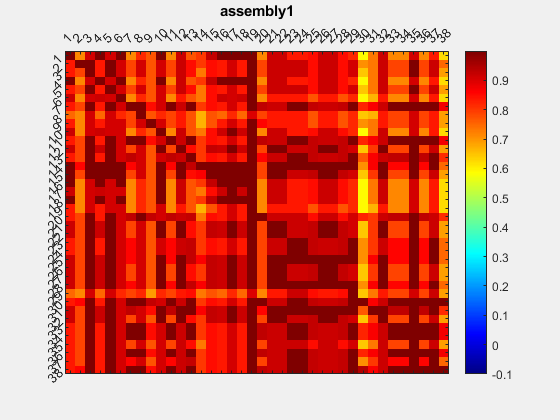


figure(Visible="on")
imagesc(similarity_matrix1)
xticks(1:numel(result)) 
xtickangle(45) 
xticklabels(result)
yticks(1:numel(result)) 
ytickangle(45) 
yticklabels(result)
ax = gca;
ax.XAxisLocation = 'top';
colormap (jet)
colorbar
clim([-0.1 1])
title('assembly1')

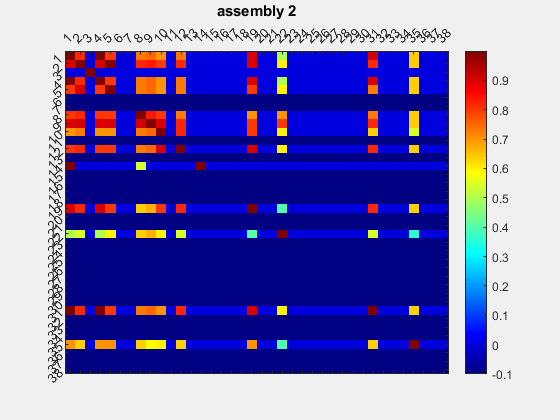



figure(Visible="on")
imagesc(similarity_matrix2)
xticks(1:numel(result)) 
xtickangle(45) 
xticklabels(result)
yticks(1:numel(result)) 

ytickangle(45) 
yticklabels(result)
ax = gca;
ax.XAxisLocation = 'top';
colormap (jet)
colorbar
clim([-0.1 1])
title('assembly 2')

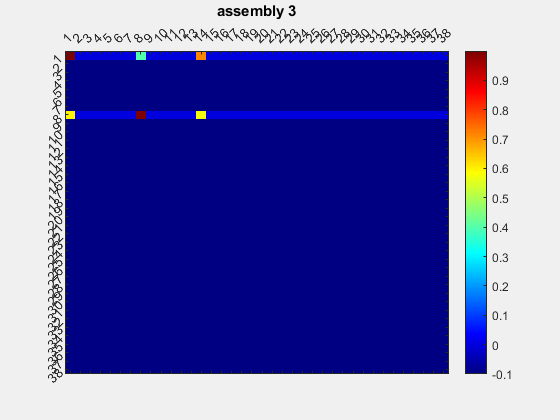


figure(Visible="on")
imagesc(similarity_matrix3)
xticks(1:numel(result)) 
xtickangle(45) 
xticklabels(result)
yticks(1:numel(result)) 
ytickangle(45) 
yticklabels(result)
ax = gca;
ax.XAxisLocation = 'top';
colormap (jet)
colorbar
clim([-0.1 1])
title('assembly 3')

% figure(Visible="on")
% imagesc(similarity_matrix4)
% xticks(1:numel(result)) 
% xtickangle(45) 
% xticklabels(result)
% yticks(1:numel(result)) 
% ytickangle(45) 
% yticklabels(result)
% ax = gca;
% ax.XAxisLocation = 'top';
% colormap (jet)
% colorbar
% clim([-0.1 1])
% title('assembly4')

mean(similarity_matrix1(1:10,1:10),"all")

ans = 0.8729

mean(similarity_matrix1(11:19,11:19),"all")

ans = 0.9020

mean(similarity_matrix1(20:28,20:28),"all")

ans = 0.9410

mean(similarity_matrix1(29:38,29:38),"all")

ans = 0.9063

mean(similarity_matrix1(25:30,25:30),"all")

ans = 0.9139